## Теория

Система уравнений, по которой строится модель:


$$\begin{cases}
U+\epsilon=RI+L \frac{dI}{dt} \\
M+M_{ext}=J\frac{d\omega}{dt}+\lambda\omega \\
M=K_mI \\
\epsilon=-K_\omega\omega
\end{cases}$$



$$U - напряжение,\ В \\
\epsilon - ЭДС\ самоиндукции,\ В \\
R -сопротивление,\ Ом \\
I - ток,\ А \\
L - индуктивность,\ Гн \\
M - момент\ двигателя,\ Н\cdotм \\
M_{ext} - момент\ внешней\ нагрузки\ на\ валу\ двигателя,\ Н\cdotм \\
J-момент\ инерции\ ротора,\ кг\cdot м^2 \\
\omega - угловая\ скорость,\ \frac{рад}{с} \\
\lambda - коэффициент\ трения \\
K_m - постоянная\ момента,\ \frac{Н\cdotм}{А} \\
K_{\omega} - постоянная\ ЭДС,\ \frac{В\cdotс}{рад}
$$


Система уравнений записывается в форме "вход - состояние - выход":


$$\dot{x}=Ax+Bu \\
y = Cx+Du$$


Здесь $x$ - вектор состояния, $\dot{x}$ - скорость изменения вектора состояния, матрица $A$ "описывает поведение" модели, матрица $B$ - описывает влияение управления на систему, $u$ - управление, $y$ - выход системы, матрица $C$- выбор элемента вектора состояния, который хотим измерять, матрица $D$ описывает влияние управления на выход системы. Обычно $D$ принимают 0.

Первая строка "вход-состояние", потому что в ней присутствует вход в модель (управление) - $u$, и состояние - $x$. Вторая строка "выход", потому что там присутствует $y$ - выход системы. По сути то, что мы измеряем датчиками.

Представить модель в данной форме можно разными способами, в зависимости от выбора вектора состояния. Например, можно взять вектор состояния в виде тока и угловой скорости.

syms w I
x = [w ; I]

$$x = \left(\begin{array}{c} w\\ \text{I} \end{array}\right)$$

Выбор вектора состояния зависит от целей. Чем больше элементов мы добавляем (при условии, что мы можем их описать уравнениями), тем больше информации о системе у нас будет, но тем больше нужно будет проводить вычислений.

Любую модель можно представить в форме "вход - состояние - выход" и использовать готовые инструменты для работы с моделью. Например в simulink есть блок State-Space. В его параметры записываются матрицы A B C D и задаются начальные значения вектора состония. 

## Практика

Это параметры из даташита случайного привода maxon. Номинальное напряжение 12 В. Холостой ход - подали 12 В, на валу нет внешней нагрузки. Номинальная угловая скорость - 12 В при номинальной нагрузке.

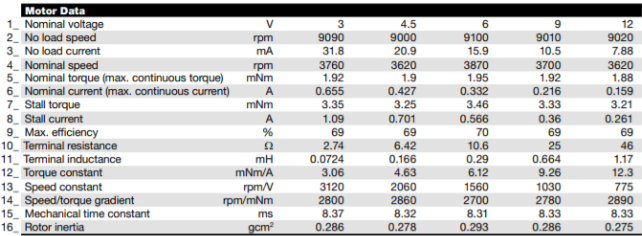

### Записываем все переменные

J = 0.275e-7; %момент инерции ротора
R = 46; %сопротивление
L = 1.17e-3; %индукция
Kw = 0.012; %постоянная ЭДС
Km = 12.3e-3; %постоянная момента
Ihh = 7.88e-3; %ток холостого хода
Whh = pi/30*9020 %rad/s (9020 rpm / 60 * 2 * pi) % скорость холостого хода

Whh = 944.5722

Lam = Km*Ihh/Whh; %лямбда - коэффициент трения (??? переход от скорости к моменту???)
Wnominal = pi/30 * 3620; % номинальная угловая скорость
Mhh = Km*Ihh

Mhh = 9.6924e-05


A = [-Lam/J Km/J; -Kw/L -R/L]

A = 1.0e+05 *

   -0.0000    4.4727
   -0.0001   -0.3932


B = [-1/J 0; 0 1/L]

B = 1.0e+07 *

   -3.6364         0
         0    0.0001


C = [1 0; 0 1]

C =      1     0
     0     1


D = [0 0; 0 0]

D =      0     0
     0     0


### Проводим симуляцию и выводим графики

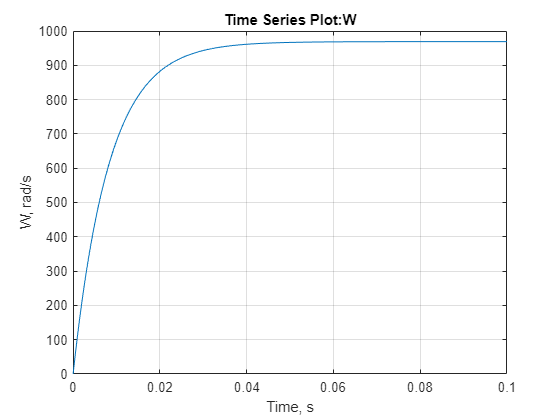

o = sim('motor_sim').simout;
o_original = 0;

gplot(o.W, 'Time, s', 'W, rad/s')

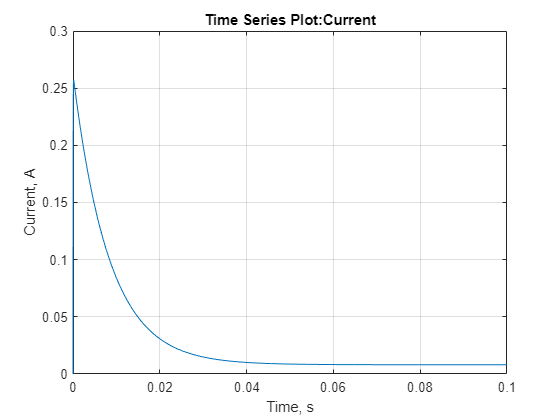

gplot(o.Current, 'Time, s', 'Current, A')

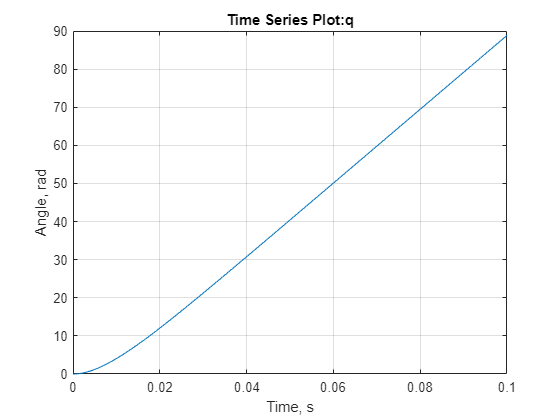

gplot(o.q, 'Time, s', 'Angle, rad')

## Идентификация

% две основные формулы
% Km*I(t) = J*dw/dt + Lam*w(t)
% U(t) - Kw*w(t) = RI(t) + L * dI/dt

Берем вторую формулу в таком виде:


$$\frac{d\omega}{dt}=\frac{K_mI(t)-\lambda\omega(t)}{J}$$


Заменяем $I\left(t\right)$ на $I_{\textrm{hh}}$ (функцию тока на константу равную току холостого хода)

syms w(t) J Lam I(t) Kw L Km U(t) Mhh Ihh

U = 12

U = 12


% решаем дифф уравнение и получаем функцию w(t)
sw = dsolve( diff(w,t) == (Km*Ihh-Lam*w)/J, w(0)==0 )

$$sw = \frac{\mathrm{Ihh}\,\mathrm{Km}-\mathrm{Ihh}\,\mathrm{Km}\,{\mathrm{e}}^{-\frac{\mathrm{Lam}\,t}{J}}}{\mathrm{Lam}}$$

% sw = dsolve( diff(w,t) == (Mhh-Lam*w)/J, w(0)==0 )

## Метод наименьших квадратов

syms w(t) J Lam I(t) Kw L Km U(t) Whh R Ihh f
wt = Whh - Whh * exp(-Lam/J * t)

$$wt = \mathrm{Whh}-\mathrm{Whh}\,{\mathrm{e}}^{-\frac{\mathrm{Lam}\,t}{J}}$$

% wt = sw

f = 0;
length(o.W.Time)

ans = 1049

% for i = 1:length(o.W.Time)
for i = 1:50:1000
    t = o.W.Time(i);
    f = f + ( subs(wt) - o.W.Data(i) )^2;
    f = vpa(f,3);
end

f = simplify(f);

В теории, ток холостого хода можно измерить самому вручную - подать номинальное напряжение и посмотреть на значения тока в установившемся режиме вращения

Ihh = 0.008

## Частные производные по неизвестным параметрам

dJ = diff(f, J);
dLam = diff(f, Lam);
dWhh = diff(f, Whh);

% dJ = diff(f, J);
% dLam = diff(f, Lam);
% dKm = diff(f, Km);
% dIhh = diff(f, Ihh);

### Решение системы уравнений

solution = solve([dJ, dLam, dWhh], [J, Lam, Whh]);

% solution = solve([dJ, dLam, dKm, dIhh], [J, Lam, Km, Ihh]); 

solution.J

$$ans = \left(\begin{array}{c} -258.01963746253027151791703818807\\ 32.129395839052939786437753264447\\ 0 \end{array}\right)$$

solution.Lam

$$ans = \left(\begin{array}{c} 1.8358611823920756676903447301343e-40\\ 3866.729879271199728418740114438\\ 0 \end{array}\right)$$

solution.Whh

$$ans = \left(\begin{array}{c} -3.1764143231001961053913097023706e-59\\ 969.11919350492965725925037361815\\ 0 \end{array}\right)$$


% solution.J
% solution.Lam
% solution.Km
% solution.Ihh

### Сравнение графиков решения и модели

syms t
n = 2

n = 2

J = solution.J(n)

$$J = 32.129395839052939786437753264447$$

Lam = solution.Lam(n)

$$Lam = 3866.729879271199728418740114438$$

Whh = solution.Whh(n)

$$Whh = 969.11919350492965725925037361815$$

w = subs(wt)

$$w = 969.11919350492965725925037361815-969.11919350492965725925037361815\,{\mathrm{e}}^{-120.34866446418611400469220245886\,t}$$

w = vpa(w,3)

$$w = 969.0-969.0\,{\mathrm{e}}^{-120.0\,t}$$

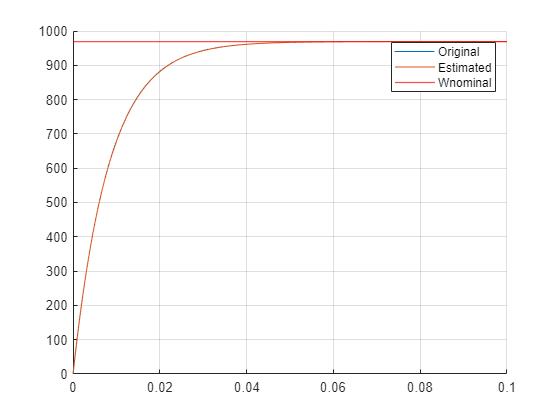


figure
hold on;
plot(o.W)
fplot(w)
yline(o.W.Data(length(o.W.Data)),'Color','red', 'LineWidth', 1)
grid on
xlim([0 0.1])
ylim auto
hold off
legend("Original", "Estimated", "Wnominal")

% e -> estimated (оценка)
syms eWhh eIhh eKw eKm eJ eR eL eLam eMhh w(t) x y t

w0 = 0
% eWhh = 969
% eIhh = 0.008
% eMhh = Km*Ihh
% eJ = J
% eLam = Lam
% 
% 
% w(t) = (w0 - eMhh/(eJ*eLam))*exp(-eLam*t) + eMhh/(eJ*eLam)
% q(t) = int(w(t), t)
% vpa(q,3)
% 
% figure
% fplot(q)
% grid on
% xlim([0 0.1])
% % ylim([0 1])
% ylim auto

Mhh = Km*Ihh
% Lam = Km*Ihh/Whh
% Lam = Lam
% Whh

% w(t) = (w0 - Mhh/(J*Lam))*exp(-Lam*t*1e9) + Mhh/(J*Lam);
% w(t) = (w0 - Mhh/Lam)*exp(-Lam*t*35/J) + Mhh/Lam;
% w(t) = (w0 - Whh)*exp(-Lam*t/J) + Whh;
% w(t) = Whh * ( 1 - exp((-Mhh*t)/(J*Whh)) )
% w(t) = w(t)/(0.355*10e7);
% Lam;
% 1/Lam;

% w(t) = Mhh/Lam - Mhh/Lam * exp(-Lam/J * t)
Whh = 969
w(t) = Whh - Whh * exp(-Lam/J * t)
% Mhh/Lam

o.W.Data(length(o.W.Data))
figure
hold on;
plot(o.W)
yline(o.W.Data(length(o.W.Data)),'Color','red', 'LineWidth', 1)
fplot(w)
grid on
% xlim([0 10/Lam])
% xlim([0 (10/Lam)/1e9])
xlim([0 2])

% ylim([0 1])
% ylim auto
hold off


% M = J*dw/dt + Lam*w
% U - Kw*w = RI + L * dI/dt
% Km*I = J*dw/dt + Lam*w

syms w(t) J Lam I(t) Kw L Km U(t)

U = 12

eqns = [ diff(I,t) == (U - Kw*w - R* I)/L , diff(w,t) == (Km*I-Lam*w)/J ]
Dw = diff(w,t)
DI = diff(I,t)
cond = [ w(0) == 0 , I(0) == 0]

% dsolve( diff(w,t) == (Lam*w-M(t))/J, w(0)==0 )
S = dsolve(eqns, cond)
S.w;
S.I;

J = 0.275e-7; %момнет инерции ротора
R = 46; %сопротивление
L = 1.17e-3; %индукция
Kw = 0.012; %постоянная ЭДС
Km = 12.3e-3; %постоянная момента
Ihh = 7.88e-3; %ток холостого хода
Whh = pi/30*9020 %rad/s (9020 rpm / 60 * 2 * pi) %скорость холостого хода
Lam = Km*Ihh/Whh; %лямбда - коэффициент трения (??? переход от скорости к моменту???)
Wnominal = pi/30 * 3620; % номинальная угловая скорость

sol = subs(S.w);
cur = subs(S.I);

% figure
% hold on;
% % plot(o.W)
% % fplot(sol)
% fplot(vpa(sol,3))
% grid on
% xlim([0 0.1])
% ylim auto
% % ylim([0 10000])
% hold off

t = 0:0.0001:0.1;
vpa(subs(sol), 3);
v = double(vpa(subs(sol), 3));
i = double(vpa(subs(cur), 3));

figure
hold on;
plot(o.W)
plot(t, v)
grid on
xlim([0 0.1])
ylim auto
% ylim([0 10000])
hold off

figure
hold on;
% plot(o.W)
plot(t, i)
grid on
xlim([0 0.1])
ylim auto
% ylim([0 10000])
hold off

syms w(t) J Lam I(t) Kw L Km U(t) Mhh

U = 12

%1
% sw = dsolve( diff(w,t) == (Mhh-Lam*w)/J, w(0)==0 )

%2
I=si;
sw = dsolve( diff(w,t) == (Km*I-Lam*w)/J, w(0)==0 )
Whh = 969
Ihh = 0.008
Mhh = Km*Ihh
Lam = Mhh/Whh

sw = subs(sw)
sw = simplify(sw)

syms w(t) J Lam I(t) Kw L Km U(t) Ihh R Mhh Whh

U = 12
Mhh = Km*Ihh
Lam = Mhh/Whh
% Lam = Km*Ihh/Whh

% Whh = 969
% Ihh = 0.008

% w = sw
% w = subs(sw)

% 2
% si = dsolve( diff(I,t) == (U - Kw*w - R*I)/L, I(0)==0 );
% si = simplify(si)
% si = subs(si)

% 1
si = dsolve( diff(I,t) == (U - Kw*Whh - R*I)/L, I(0)==0 );
si = simplify(si)
% si = subs(si)